# **Digital Communication Systems CA3**

## Golmehr Khosrokhavar - Stident ID : 810198507

### Generting Raised Cosine PULSE : 

- Here we define given parameters in the assignment. Then we are going to generate Raised Cosine Pulse

Beta = 0 ;
T = 1; 
Fs = 10 ; 
L = T*Fs; 
delta_t = T/Fs;

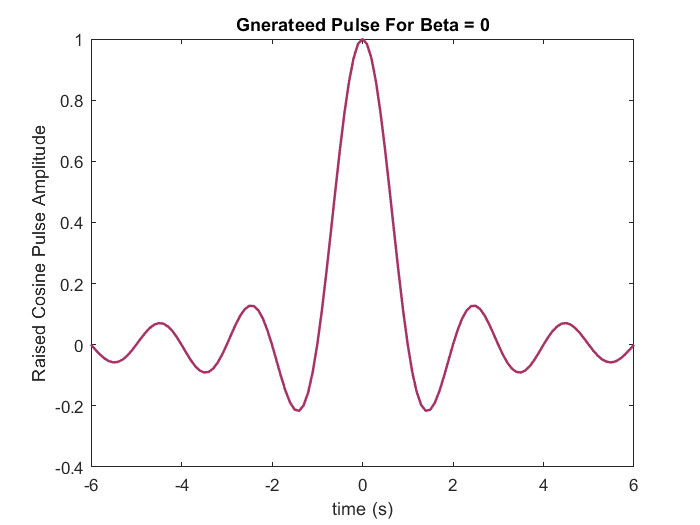

sampling_error1 = 0 ; 
t1 = (-6*L : 6*L)/Fs - sampling_error1;
P_r_zeros = zeros (1, length(t1));
P_r = pulse_generator(t1,Beta,T);

plot (t1,P_r,'LineWidth',1.5,'Color',[0.65, 0.2, 0.4])
xlabel('time (s)'); ylabel('Raised Cosine Pulse Amplitude');
title ('Gnerateed Pulse For Beta = 0');

### Generating Modulated Symbols : 

as discussed in the assignment, first we make a vector of ${10}^6$ indexes. which is called "bits" and contains random values between -3, -1, 1 , 3 (uniformly distributed)

"modulated_symbols" is a vector with same size of bits and contains the coded values

bits =  rand(1,1000000);

modulated_symbols = zeros(1, length(bits));

for i = 1 : length(bits)
    if ((bits(i) > 0)&&(bits(i) < 0.1))
        modulated_symbols(i) = -3; %%  A
    elseif ((bits(i) > 0.1)&&(bits(i) < 0.5))
        modulated_symbols(i) = -1; %%  B
    elseif ((bits(i) > 0.5)&&(bits(i) < 0.9))
        modulated_symbols(i) = 1; %%  C  
    elseif (bits(i) > 0.9)
        modulated_symbols(i) = 3; %%  D          
    end
end


### Upsampling : adding L-1 zeros between each two elements. 

we suppose if each analog span has a length of T and we want to replace it with L samples. Hence we have to add L -1 zeros between each two samples. 

temp0 = upsample(modulated_symbols,L);
temp0 = temp0(1:end-(L-1));

### Convolving Upsampled vector of symbols with the raised cosine puse, generated in first part. 

transmitted_signal1 = conv(P_r,temp0);

### Simmulating AWGN channel

First we have to find E_s which is calculated by the expected value of symbols.

Es = 0.1.*(9) + 0.4.*(1)+0.4.*(1)+0.1.*(9);

SNR_dB = 0:10;
etta = zeros(1,length(SNR_dB));
 for i = 1:length(etta)
     etta(i) = find_etta(SNR_dB(i),Es);
 end
  Zarib = zeros(1,length(etta));
 Noise = randn(11,length(transmitted_signal1));
 
  for i = 1:length(etta)
      Zarib(i) = sqrt(etta(i)/2);
      Noise(i,:) = Zarib(i).*Noise(i,:);
  end
  

### Generating received signals

  received_signal1 = create_recieved_signal(etta,Noise,transmitted_signal1);
  

### Generating Samples

In this part we calculate "received-signal"in sampling times and generate a new vector, named "samples"

 N = 10.^6;
T_sampling = 6*L+1:L:(N+6-1)*L+1;
samples1 = create_samples(T_sampling,received_signal1);

### PSI Curves 

etta = 10

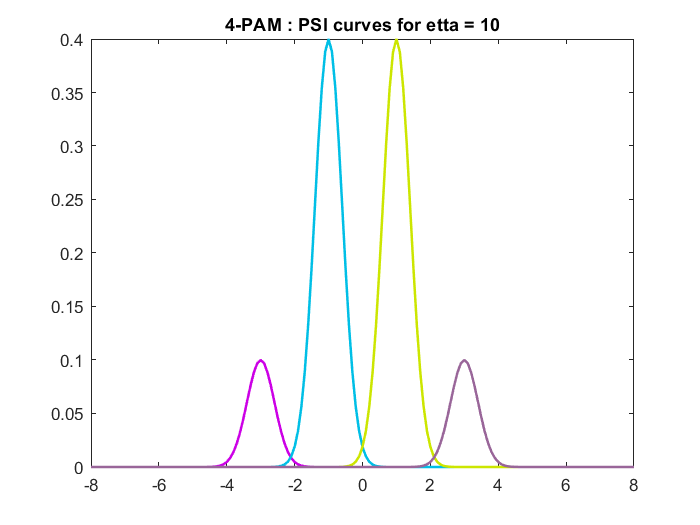

y = -8:0.1:8;
PSI_A = 0.1.*exp((-1/etta(10)).*((y-(-3)).^2));
PSI_B = 0.4.*exp((-1/etta(10)).*((y-(-1)).^2));
PSI_C = 0.4.*exp((-1/etta(10)).*((y-(1)).^2));
PSI_D = 0.1.*exp((-1/etta(10)).*((y-(3)).^2));

plot(y,PSI_A,'LineWidth',1.5,'Color',[0.8 0 0.9]);
hold on
plot(y,PSI_B,'LineWidth',1.5,'Color',[0 0.75 0.9]);
plot(y,PSI_C,'LineWidth',1.5,'Color',[0.8 0.9 0]);
plot(y,PSI_D,'LineWidth',1.5,'Color',[0.6 0.4 0.6]);
title ('4-PAM : PSI curves for etta = 10');
hold off

etta = 1

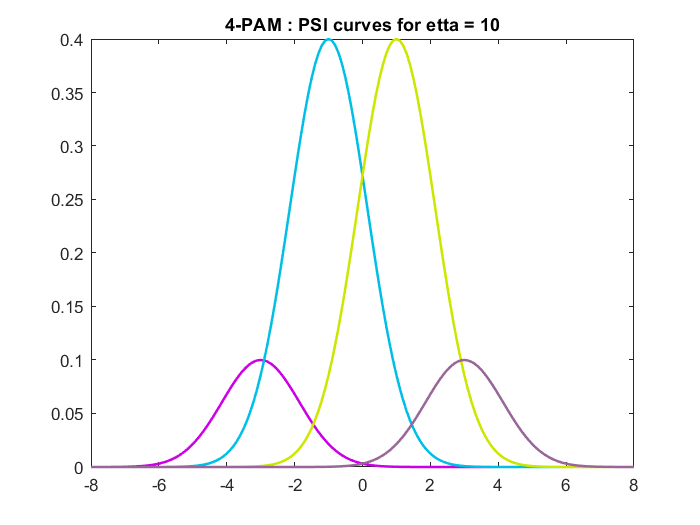

PSI_A1 = 0.1.*exp((-1/etta(1)).*((y-(-3)).^2));
PSI_B1 = 0.4.*exp((-1/etta(1)).*((y-(-1)).^2));
PSI_C1 = 0.4.*exp((-1/etta(1)).*((y-(1)).^2));
PSI_D1 = 0.1.*exp((-1/etta(1)).*((y-(3)).^2));

plot(y,PSI_A1,'LineWidth',1.5,'Color',[0.8 0 0.9]);
hold on
plot(y,PSI_B1,'LineWidth',1.5,'Color',[0 0.75 0.9]);
plot(y,PSI_C1,'LineWidth',1.5,'Color',[0.8 0.9 0]);
plot(y,PSI_D1,'LineWidth',1.5,'Color',[0.6 0.4 0.6]);
title ('4-PAM : PSI curves for etta = 1');
hold off

#### Notable points:

as demonstrated in two PSI curves for Etta=10 and Etta=1 ; we can conclude that as etta increases, PSI curves are seperated from each other and areas which are under 2 psi curves, are minimized, which will cause a decrease in Error probability. 

### Calculating tresholds

### MAP tresholds : 

## 
$$\psi_A =0\ldotp 1e^{\left(\frac{-{\left(y+3\right)}^2 }{\eta }\right)}$$


## 
$$\psi_B =0\ldotp 4e^{\left(\frac{-{\left(y+1\right)}^2 }{\eta }\right)}$$


## 
$$\psi_C =0\ldotp 4e^{\left(\frac{-{\left(y-1\right)}^2 }{\eta }\right)}$$


## 
$$\psi_D =0\ldotp 1e^{\left(\frac{-{\left(y-3\right)}^2 }{\eta }\right)}$$


#### As plotted above, tresholds are bieng find from the intersection points between each two PSI curves, 

#### I have used matlab to calculate the 3 tresholds as a function of etta

P_1 = [0.1, 0.4, 0.4]; miu_1 = [-3, -1, 1];
P_2 = [0.4, 0.4, 0.1]; miu_2 = [-1, 1 , 3];

for i = 1:3
    syms ettta y
    eqn = P_1(i).*exp((-1/ettta).*((y-miu_1(i)).^2)) - P_2(i).*exp((-1/ettta).*((y-miu_2(i)).^2)) ==0;
    S(i) = solve(eqn);
end
S

$$S = \left(\begin{array}{ccc} -\frac{\mathrm{ettta}\,\log\left(2\right)}{2}-2 & 0 & \frac{\mathrm{ettta}\,\log\left(2\right)}{2}+2 \end{array}\right)$$

#### While MAP tresholds are calculated as a function of etta, we know that ML treshholds do not depend on Posteriori Probabilities. 

#### we can suppose that ML tresholds are symmetrical. so they will be [-2, 0 , 2] for all values of etta. 

delta = zeros (3, 11);
delta_ML = zeros (3, 11);

for  i = 1:11
    delta(1,i) = (-etta(i)/2).*log(2) - 2;
    delta(2,i) = 0;
    delta(3,i) = ( etta(i)/2).*log(2) + 2;
    delta_ML(:,i) =  [-2,0,2];
end

### Detecting Symbols : 

.

#### Here we compare "samples" with the thresholds, which are known from the section above,

#### then we could decide whether  the transmitted signal was either -3 , -1 , 1 or 3.

detected_symbols_MAP = zeros(11,N);
detected_symbols_ML = zeros(11,N);

detected_symbols_MAP = find_detected_symbols1(T_sampling,samples1,delta);
detected_symbols_ML = find_detected_symbols1(T_sampling,samples1,delta_ML);

#### calculating number of errors:

num_of_errors_MAP = find_num_of_errors(T_sampling,modulated_symbols,detected_symbols_MAP);
num_of_errors_ML = find_num_of_errors(T_sampling,modulated_symbols,detected_symbols_ML);

### Calculating Error Probability : 

we consider error probability be : 

P_e1_MAP = num_of_errors_MAP/N;
P_e1_ML = num_of_errors_ML/N;

### Plotting the results:

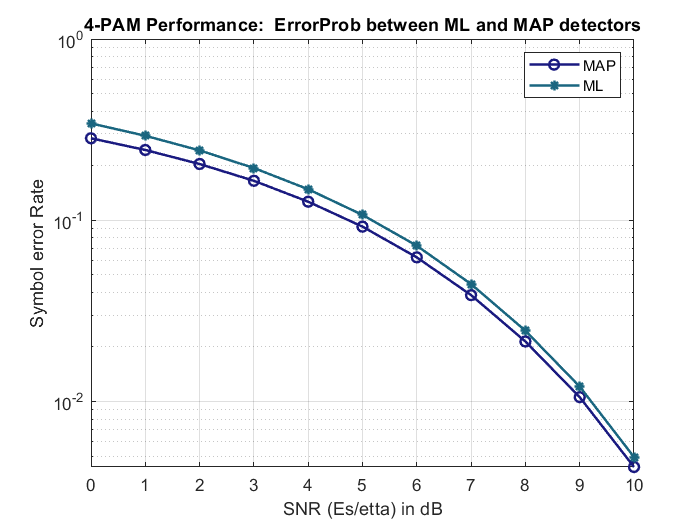

p1 =semilogy (SNR_dB , P_e1_MAP,'LineWidth',1.5);
p1.Color = [0.1,0.1,0.5];
p1.Marker = "o";
hold on 

p2 =semilogy (SNR_dB , P_e1_ML,'LineWidth',1.5);
p2.Color = [0.1,0.4,0.5];
p2.Marker = "*";

grid on
legend('MAP ','ML');
title ('4-PAM Performance:  ErrorProb between ML and MAP detectors');
xlabel('SNR (Es/etta) in dB'); ylabel ('Symbol error Rate');
hold off

### **Conclusion**

It can be observed from above graghs that MAP detector has more accuracy and its error probability is less,in comparison with ML detector. . 

## Functions

function etta = find_etta(SNR_dB,Es)
   temp = 0.1.*SNR_dB;
   etta = Es/(10.^(temp));
end

function P_r = pulse_generator(t1,Beta,T)
    p_1 = zeros (1, length(t1));
    m1 = find(abs(t1-(T/(2*Beta)))<0.0000000000000001);
    m2 = find(abs(t1+(T/(2*Beta)))<0.0000000000000001);
    for i1 = 1: length(t1)
        i = t1(i1);
        if i1==m1
            P_r(i1) = (pi/4).*sinc(1./(2.*Beta));
        elseif i1==m2
            P_r(i1) = (pi/4).*sinc(1./(2.*Beta));
        else 
            P_r(i1) = sinc(i./T).*cos(pi.*Beta.*i/T)/(1-(2.*Beta.*i/T).^2);
        end
       
    end
end

function received_signal1 = create_recieved_signal(etta,Noise,transmitted_signal1)
   received_signal1 = zeros(11, length(transmitted_signal1));
   for i = 1:length(etta)
       received_signal1(i,:)= transmitted_signal1 + Noise(i,:);
   end
end

function samples1 = create_samples(T_sampling,received_signal1)
samples1 = zeros(11, length(T_sampling));

    for j = 1 :11
       for i = 1: length(T_sampling)
           samples1(j,i)=received_signal1(j,T_sampling(i));     
       end
    end  
end

function detected_symbols1 = find_detected_symbols1(T_sampling,samples1,delta)

    detected_symbols1 = zeros(11,length(T_sampling));
    for j = 1:11
        for i = 1: length(T_sampling)
        
            if ( samples1(j,i) <= delta(1,j) )
                detected_symbols1(j,i) = -3;
            elseif((samples1(j,i) > delta(1,j)) & (samples1(j,i) <= delta(2,j)))
                detected_symbols1(j,i) = -1;
            elseif((samples1(j,i) > delta(2,j)) & (samples1(j,i) <= delta(3,j)))
                detected_symbols1(j,i) = 1; 
            elseif(samples1(j,i) > delta(3,j)) 
                detected_symbols1(j,i) = 3;                
            end  
            
        end
    end 
end

function  num_of_errors1 = find_num_of_errors(T_sampling,modulated_symbols,detected_symbols1)
num_of_errors1 = zeros(11,1);

for j = 1:11
    for i = 1: length(T_sampling)
        
       if (modulated_symbols(i) == detected_symbols1(j,i))
           num_of_errors1(j,1)= num_of_errors1(j,1);
       else 
           num_of_errors1(j,1)= num_of_errors1(j,1) +1;
       end
 
    end
end 
end